## This code generates randomly positioned spheres in a 2D plane with radii

## given by a set distribution. Material properties are assigned to each

## sphere, then electromagnetic simulaitons (MSTM) are run and the results are

## stored in a structure. 

## This code is designed to approximate the properties of an infinate 2D

## random particle film by simulating multiple finite sized, but sufficiently

## large, simulations. Multiple layers of parallel processing is used to

## minimize computation time. 

## The simulation sweeps over:

## 1)  Center particle radius.

## 2) Cluster fill fraction (2D film).

## 3) Unique particle distributions of (1) and (2) for statistics. 

## 4) Wavelength/material properties.

## 5) Plane wave polarization at normal incidence.

clear;
clc;

# SPECIFY IF YOU WANT TO SAVE THE RESULTS OF THE SIMULATION

SAVE_FLAG = 0;

# SPECIFY RELEVANT DIRECTORIES 

% Paths to import programs.
addpath(genpath('/home/elipaul/hypnos/MSTMwrapper')); 
addpath(genpath('/home/elipaul/hypnos/codes/Matlab Functions'));  
addpath(genpath('/home/elipaul/hypnos/codes/randomparticles'));  

% Location of the fortran compiled run program for MSTM code.
mstm_location = '/home/elipaul/hypnos/MSTMwrapper/mstm_parallel_ubuntu.out';
mstm_location_serial = '/home/elipaul/hypnos/MSTMwrapper/mstm_serial_ubuntu.exe';

% Specify the directory where you will place input and output files for
% communicating with the MSTM fortran program. Save files will also go to
% this location. 
parentdir = uigetdir('/home/elipaul/hypnos',' Specify Save Directory'); % for Linux
%parentdir = uigetdir('$ME','Specify Save Directory'); % for NERSC

% Change directory to location where input/output files are saved
oldFolder = cd(parentdir);

# SPECIFY GENERAL PARAMETERS FOR MSTM RUN

## Set flags for MSTM run

mstm_flags = struct('write_sphere_data', 1,...
    'store_translation_matrix', 0,...
    'normalize_scattering_matrix',0,...
    'fixed_or_random_orientation',0,...
    'calculate_scattering_coefficients',1,...
    'track_nearfield_iterations',1,...
    'calculate_near_field',0,...  
    'calculate_t_matrix', 0,...   
    'azimuth_average_scattering_matrix',0);

## Define parameters for solution convergence

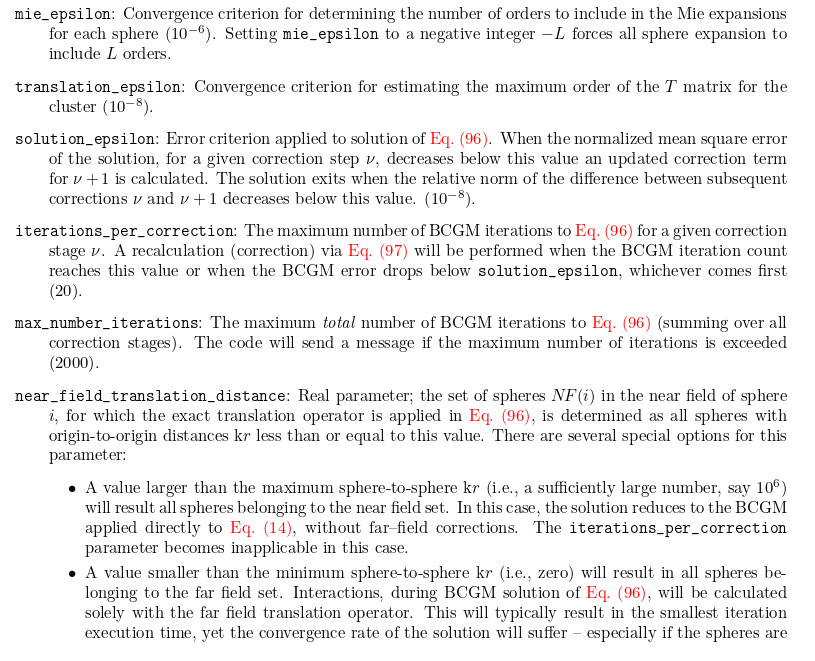

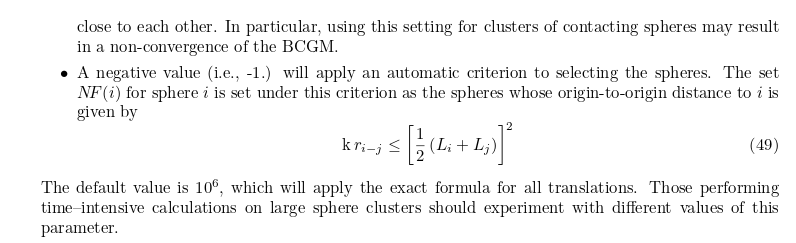

convergence = struct(...
    'mie_epsilon', 10^-5,...
    'translation_epsilon', 10^-5,...
    'solution_epsilon', 10^-5,...
    'max_number_iterations', 1000,...
    'plane_wave_epsilon',10^-5,...
    't_matrix_convergence_epsilon',10^-5,...    
    'sm_number_processors', 1000,...
    'iterations_per_correction', 30);
% NOTE: near_field_translation_distance is hard coded

## Define parameters for the input beam.

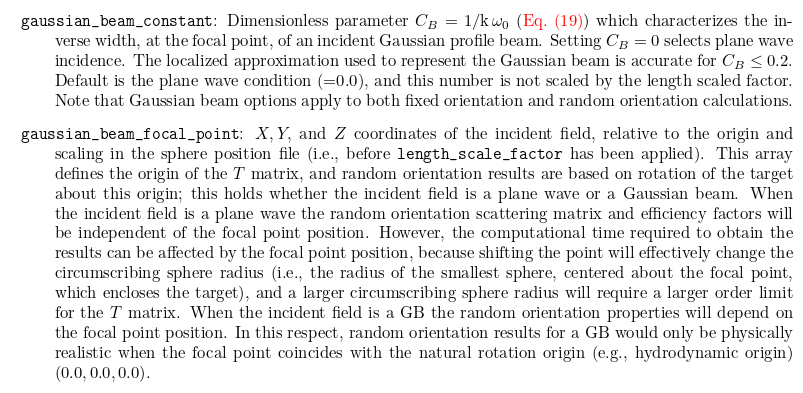

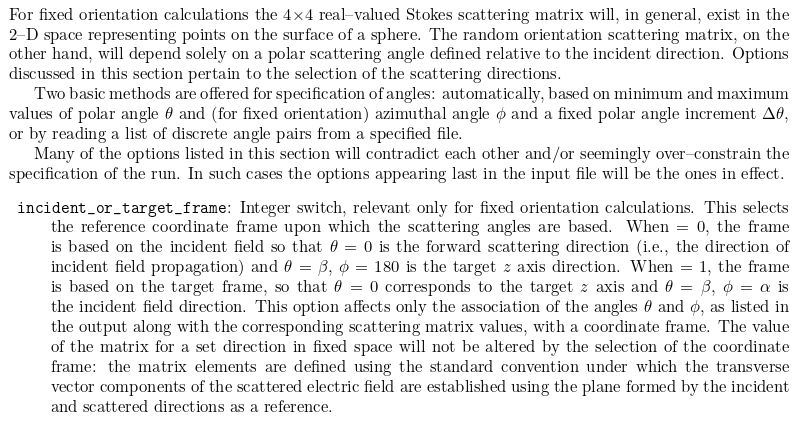

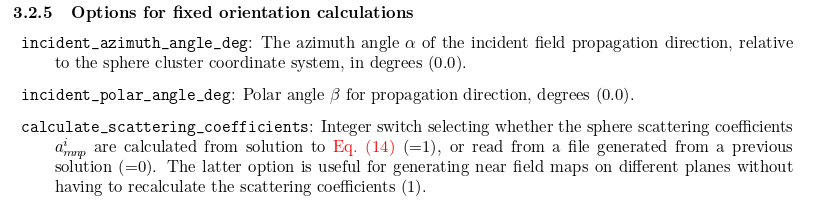

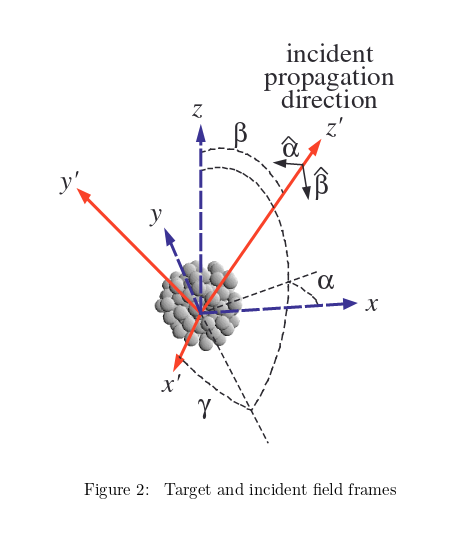

input_beam = struct(...
    'incident_or_target_frame', 0,... 
    'gaussian_beam_width', [],...
    'beam_type', 0,... % 0 = plane wave, 1 = Gaussian beam
    'incident_azimuth_angle_deg', 0,... % Alpha
    'incident_polar_angle_deg', 0,... % Beta 90 = supression
    'polarization_angle_deg',0); % Gamma

## Define parameters for near field calculations

near_field = struct(...
    'plane_cord',2,...
    'plane_position',0,...
    'plane_vertices',[-3000,-3000,3000,6000],...
    'resolution',0.5,...
    'near_field_output_data',2);

## Define parameters for particle distribution

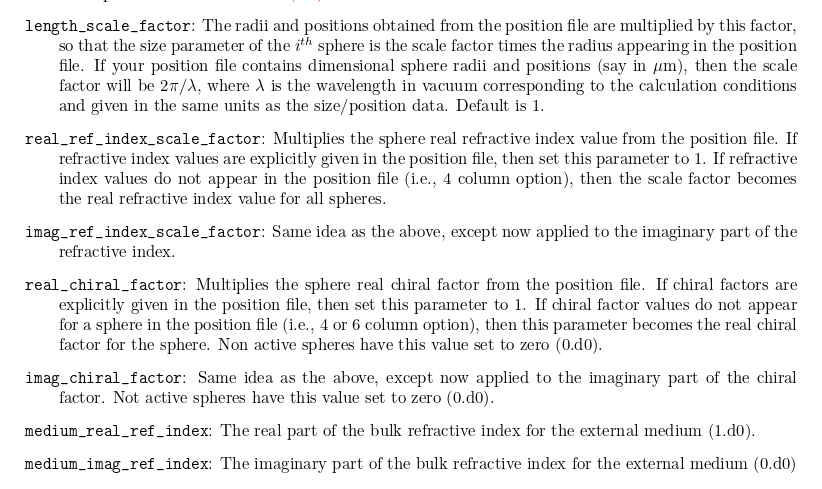

mstm_input_params = struct(...
    'Nspheres', [],... 
    'k',[],... % length_scale_factor 
    'real_ref_index_scale_factor', 1,...
    'imag_ref_index_scale_factor',1,...
    'real_chiral_factor', 0,...
    'imag_chiral_factor', 0,...
    'medium_real_ref_index',1,...
    'medium_imag_ref_index',0,...
    'medium_real_chiral_factor',0,...
    'medium_imag_chiral_factor',0);

# SPECIFY SWEEP PARAMETERS FOR MSTM TO RUN

`Goal:`

Our goal is to look at the mode profiles in particles as they interact with other particles based on random radii and position. We then compare that result to the case if that  particle were isolated in free space. Our goal is to study how the interparticle coupling if effecting the solution and how we can use the results to predict the behavior of infinate (very large) films of these particles. 

`Motivation:`

Modern nm-sized paterning/lithography is not scalable to large area [> um^2] as drift/small inaccuracies in position compound to create large changes. Furthermore fabrication always has tolerance issues with respect to accuracy in shape. Metamaterials can be very sensitive to these facts if they rely on specific shape and periodicity to generate the desired effect. If particles can be found that reduce these dependencies, they could possibly be implemented over ~mm^2- m^2 area. This has particular applications in solar energy research. Other photonic/metamaterial applications apply as well. 

`Parameters in this code:`

We seek to compare the modes in the center particle to its isolated counterpart. Since we are comparing to the isolated case, we need to deterministically set the radius of the center particle so we can compare apples-to-apples. We then run many different random distributions around that center particle to get the statistics on how random coupling is effecting the result. These statistics not only tell us how the particle will respond to random coupling, on average, but have a direct link to a proposed formula for predicting an infinate film response. Currently there is no complete formula for defining the optical response in an infinate random film using the MSTM method (fundamentally it is likely not possible to define). We sweep the following:

***Center particle radius:*** since our film is composed of random sizes, we want to know how each particle size is effected by the random coupling with respect to its isolated particle counterpart. 

***Fill fraction:*** Coupling properties will change as a funciton of packing density. 

***Unique distributions:*** We need to run statistics for each center particle radius. This is achieved by simulating unique distributions around the center particle.

***Wavelength:*** We are interested in the modes and material properties as a function of wavelength. 

***Polarization: ***Averaging over the two polarization states dramatically simplifies the mathematics and is valid when talking about random films. 

***Distribution parameters:  ***Looking at different types of particle distributions (e.g., normal or bimodal). Studying this parameter should likely be done in seperate code as each new distribution is likely an independent study case. THIS CODE DOES NOT SWEEP DISTRIBUTION PARAMETERS.

% Good practice to always ensure variables are cleared before assigning. 
clearvars r_mean r_sigma type dimension bounds giggles
clearvars center_radiis fill_fractions Ndistributions wavelengths polarizations
clearvars k L1 L2 L3 L4 L5 Nsimulations

% Static parameters (use singular name conventiona):
r_mean = 140;
r_sigma = 10;
type = 'film';
dimension = 2;
bounds = [4, 4, 1];
giggles = 100;
% Sweep parameters (user plural name convention):
center_radiis =[120, 130, 140, 150, 160]; % linspace(r_mean-r_sigma, r_mean+r_sigma, 3); % spacing set to have r = 140nm, to compare with  previous work
% CHOSE CENTER_RADII SPACING CAREFULLY TO MAXIMIZE USEFULLNESS IN STUDYING THE RESULT! 
fill_fractions = [0.1, 0.2];
wavelengths = linspace(500,900,81);
Ndistributions = 10; % Number of unique distributions to simulate. >=50 is found to be best but requires longer time. 
polarizations = [0,90];

k = 2*pi./wavelengths;
L1 = length(center_radiis);
L2 = length(fill_fractions);
L3 = Ndistributions;
L4 = length(wavelengths);
L5 = length(polarizations);

Nsimulations = L1*L2*L3*L4*L5;
disp(['Number of simulations: ', num2str(Nsimulations)])

Number of simulations: 16200


# LOOP OVER PARAMETERS YOU WANT TO SWEEP

NOTE: We are parallelizing on the number of unique distributions. This is usefull when we have >20 distributions, so we can make a maximum use of the parallel process. If not, we would likely want to parallelize on the wavelengths. This code sweeps a lot of parameters. If we do not parallelize these sweeps the code would take WAY too long. 

## Make the sphere distributions with material properties

Run files here that generate particle distributions that you want to simulate. It is best that this code is determined by a secondary file that can be called as a function. The output must have the standard format for a unique distribution of spheres:

Output:

spheres = Nspheres x  [r, x, y, z, n, k] 


% You need to repeat static parameters 
mstm_input_params = repmat(mstm_input_params, L1, L2, L3, L4);
input_beam = repmat(input_beam, L5);

clearvars spheres ff
for idx1 = 1:L1 % Center radiis
    clearvars center_radii
    center_radii = center_radiis(idx1);
    disp(strcat("center radius is ", num2str(center_radii)));
    for idx2 = 1:L2 % Fill fractions
        clearvars ff_desired
        ff_desired = fill_fractions(idx2);
        for idx3 = 1:L3 % Number of distributions
        %{
          Generate a particle distribution for a given desired fill fraction and center particle radius. Nspheres x [r, x, y, z]  
        %}
            clearvars shere_cords % Cord size may change, ensure variable is completely overwritten.  
            loud = 0;
            [sphere_cords, ff(idx2, idx3)] = ...
                 randomly_placed_normally_distributed_kerker_spheres(...
                 type,...
                 dimension,...
                 ff_desired,...
                 center_radii,...
                 r_mean,...
                 r_sigma,...
                 bounds,...
                 giggles,...
                 loud);
                  
            for idx4 = 1:L4 % Wavelengths
            %{
            Add wavelength dependent material properties. Save everything 
            to a cell based on the loop variables. Inside each
            cell element is [r x y z n k] for each N sheres. I.e., Nx6 
            %}
                clearvars matfile
                matfile = '/home/elipaul/hypnos/codes/Refractive Index Info/GaN_Kawashima.csv';
                spheres(idx1, idx2, idx3, idx4).distribution = give_material_properties(sphere_cords,...
                                           matfile,...
                                           wavelengths(idx4));   
                % Input params deals with lda and Nspheres so it need to
                % index both.
                mstm_input_params(idx1, idx2, idx3, idx4).k = k(idx4);       
                mstm_input_params(idx1, idx2, idx3, idx4).Nspheres = size(spheres(idx1, idx2, idx3, idx4).distribution,1);
                                           
            end
        end
    end
end
    
for idx5 = 1:L5
    % Polarization sweep is not linked to other parameters. Remove from
    % the other loop to prevent unnecessary copying. 
    input_beam(idx5).incident_azimuth_angle_deg = polarizations(idx5);

end


## Parallelize the saving of files for MSTM to read.

Data is written to text files to be read by the MSTM program. The writing process is parallelized using linear index notation. This allows for the maximum ammount of generality in the number of parameters you want to sweep as well as the maximum use of the parallelization cores. The only thing that need to be changed by the user are the output of the ind2sub function and the relevant indexes that are relevant to the sweep you desire. There is no need to add atitional for loops. 

 disp('Generating input files for MSTM')
 tic
parfor (counter = 1:Nsimulations,35)
   
    % Give a simulation file name based on linear index notation as a unique
    % identifier
    fname{counter} =...
            strcat('mstm_',... 
            sprintf( '%03d', counter ));
            
    % Convert linear index notation to vector index notation to send
    % relevant parameters to the input files for MSTM
    [idx1, idx2, idx3, idx4, idx5] =ind2sub([L1, L2, L3, L4, L5], counter);
        
    % This function generates MSTM inputs            
    make_mstm_job(parentdir,...
                        fname{counter},...
                        spheres(idx1, idx2, idx3, idx4).distribution,...
                        mstm_flags,...
                        convergence,...
                        input_beam(idx5),...
                        near_field,...
                        mstm_input_params(idx1, idx2, idx3, idx4)) 


end
 disp(['Files generated! Time: ', num2str(toc/60),'min'])
 
% Save setting used to make input files, if desired. 
if SAVE_FLAG == 1
    %Put letter "A" so the files are at the top of the folder. 
    save('A_Simulation_Input_Workspace.mat');
    save('A_Simulation_Input_File.m');
end

# RUN SIMULATION FILES

## Uncomment if running on NERSC

%nodes = '2'; time = '00:05:00'; jobs = idx; make_mstm_SLURM_KNL_array_file(parentdir, nodes, time, jobs)

## Uncomment if running on Linux

% Copy mstm program file to folder
copyfile(mstm_location, parentdir);
copyfile(mstm_location_serial, parentdir);

disp('Running simulations.')
tic
% Run parallelized simulation at a time
parfor (idx = 1:length(fname),35)
    % Run MSTM code (Specify number of cores here "-n #")
    %command{idx} = ['/usr/lib64/openmpi/bin/mpirun -n 2 ./mstm_parallel_ubuntu.out ',fname{idx},'.inp'];
    command{idx} = ['./mstm_serial_ubuntu.exe ',fname{idx},'.inp'];
    %[status,cmdout] = system(command{idx},'-echo'); 
    if ~isfile([fname{idx}, '_output.dat'])
        
        [status,cmdout] = system(command{idx});
    end
end
disp(['Simulations finished! Time: ', num2str(toc/60),'min'])

# EXTRACT MSTM DATA FOR POSTPROCESSING

Data is read from the MSTM output text files and stored in relevant cells. Thought the memory overhead is much larger using cells, it is necessary as the output of each simulaiton is a structure with variables of different sizes inside. The process of reading the MSTM output is based on parallelizing with linear index notation. This allows for the maximum amount of generality on parameters you want to sweep without needing to change the loop. The only necessary change is the reshaping of the data.  

clearvars counter cluster_data0 sphere_data0 excitation_data0 sphere_coeff_data0
disp('Reading results.')
tic

parfor (counter = 1:length(fname),35)
        
    filename = strcat(parentdir,'/',fname{counter});
    try
    [cluster_data0{counter},...
        sphere_data0{counter},...
        ~] =...
        export_output_file_v2(strcat(filename,'_output.dat'));
    
    [sphere_coeffs_data0{counter}] =...
        export_mstm_scattering_coeffs_v3(strcat(filename,'_scat_coeffs.dat'));
    catch
        disp(counter)
    end

end
disp(['Results Read! Time: ', num2str(toc/60),'min'])



## Reshape the data to match the relevant sweep parameters

clearvars cluster_data sphere_data sphere_coeffs
for counter = 1:length(fname)
    
    % Convert linear index notation to vector index notation to send
    % relevant parameters to the input files for MSTM
    [idx1, idx2, idx3, idx4, idx5] =ind2sub([L1, L2, L3, L4, L5], counter);
    cluster_data{idx1, idx2, idx3, idx4, idx5} = cluster_data0{counter};
    sphere_data{idx1, idx2, idx3, idx4, idx5} = sphere_data0{counter};
    sphere_coeffs_data{idx1, idx2, idx3, idx4, idx5} = sphere_coeffs_data0{counter};
    
end
%clearvars cluster_data0 sphere_data0 sphere_coeffs0

oldFolder = cd(parentdir);
if SAVE_FLAG == 1
    save('A_Simulation_Output_Workspace.mat'); % VERY LARGE!
    save('A_simulation_Coeffs.mat', "sphere_coeffs"); % To not have to open large file later.
end